# Dead reckoning

## Specify SD in sensor measurements

Position = 2 cm, heading = 0.5 deg

V = diag([0.02 0.5*pi/180].^2)

V = 	1.0e+-3 *

    0.4000         0
         0    0.0762


## Create car-like vehicle

rng('default'); % For consistency
veh = Bicycle('covar',V)

 
veh = 
Bicycle object                      
  L=1, steer.max=0.5, accel.max=Inf 
  Superclass: Vehicle               
    max speed=1, dT=0.1, nhist=0    
    V=(0.0004, 7.61544e-05)         
    configuration: x=0, y=0, theta=0


Note that the time between each measurement is 0.1 sec (given by veh.dt)

The vehicle starts at (0,0) with a heading of 0

### Change the max speed to 1.9

veh.speedmax = 1.9;

### Initial estimate of uncertainty

P0 = diag([0.005 0.005 0.001].^2)

P0 = 	1.0e+-4 *

    0.2500         0         0
         0    0.2500         0
         0         0    0.0100


## Make it move for one time step

### Make it drive forward at 1 m/s with a steering angle of 0.3 rad for 1 time interval

odo = veh.step(1, 0.3)

odo =     0.1108    0.0469


odo is the estimate we get from the noisy sensors

odo(1) gives the distance the vehicle moved forward along the vehicle x-axis during this time step

odo(2) the change in orientation during this time step

### The actual, but 'unknown', position and orientation of the vehicle

act = veh.x

act =     0.1000
         0
    0.0309


A column vector where act(1) is x, act(2) is y, and act(3) is theta

### The estimated position and orientation of the vehicle after one time step

est = veh.f([0 0 0],odo)

est =     0.1106    0.0052    0.0469


Give it the last (estimated) position ([0 0 0] in this case) and the estimate from the sensors 

A row vector where est(1) is x, est(2) is y, and est(3) is theta, where all values are estimates

## Alternativly, simulate one step and estimate position and heading all together

Reset things

rng('default');
veh = Bicycle('covar',V);
ekf = EKF2(veh, V, P0);

### Estimate

In order to use step_man, you need to download EKF2.m from Canvas and put it somewhere Matlab can find it

est2 = ekf.step_man(1, 0.3)

est2 =     0.1106
    0.0052
    0.0469


### Actual

act2 = veh.x

act2 =     0.1000
         0
    0.0309


## Make it move for many time steps

Reset random seed

rng('default');

### Set it up so it drives to random points

veh.add_driver(RandomPath(10))

### Run a simulation and estimate position and uncertainty

This resets the history

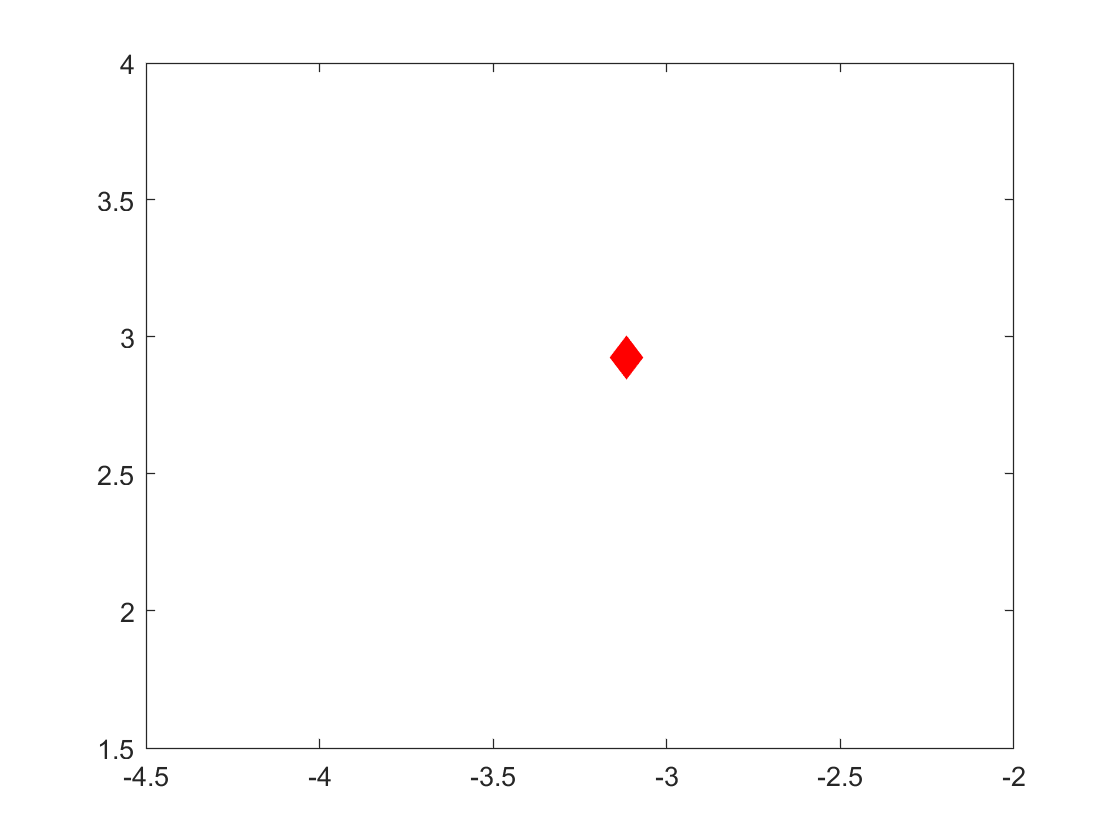

ekf.run(1000); 

The input argument says for how many time instances to run the filter on. Here we run it for 1000.

To get the history of actual states, use veh.x_hist. This gives a 1000 x 3 matrix where each row is a time instant. The first column is x, the second column is y, and the third column is theta.

To get the history of estimated states, use [ekf.history.x_est]'. This gives a 1000 x 3 matrix where each row is a time instant. The first column is x, the second column is y, and the third column is theta.

### Compare actual and estimated positions

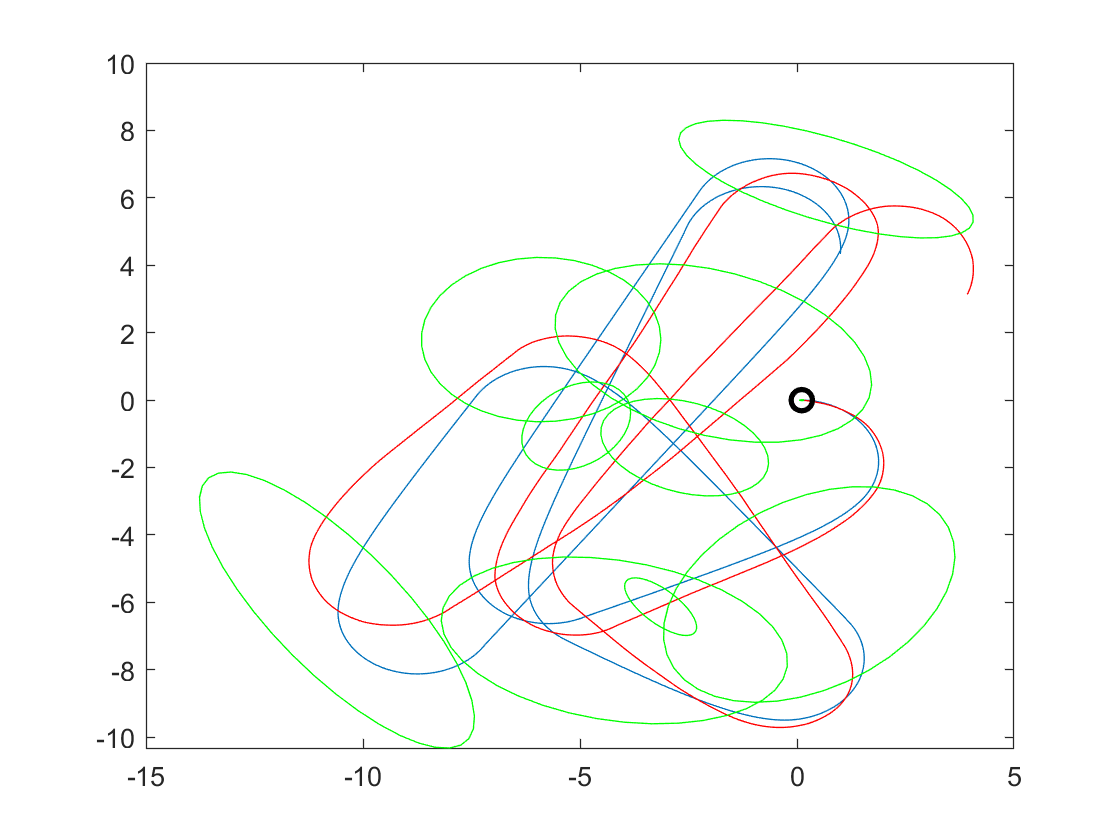

figure
veh.plot_xy() % Actual
hold on
ekf.plot_xy('r') % Estimated
ekf.plot_ellipse('g','interval',100) % Plot 95% confidence bounds every 100 time instances

### Compare confidence in first and last position

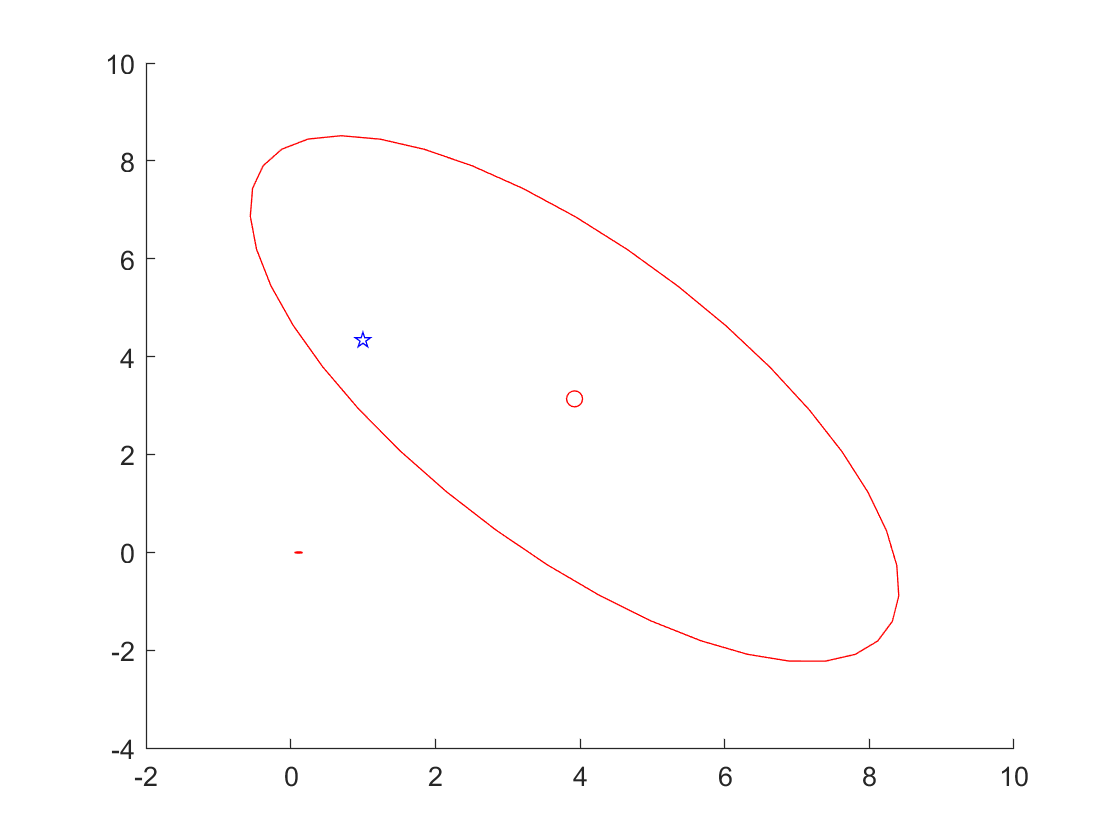

figure
ekf.plot_ellipse('r','interval',length(veh.x_hist)-1) % 95% confidence bounds
hold on
plot(ekf.history(end).x_est(1),ekf.history(end).x_est(2),'ro') % Estimated ending position
plot(veh.x(1),veh.x(2),'bp') % Actual ending position

### Estimate uncertainty in x at last position

Get the information about the last time point

h = ekf.history(end)

h = struct with fields:
    x_est: [3×1 double]
      odo: [0.0975 -0.0520]
        P: [3×3 double]
    innov: []
        S: []
        K: []


Get the expected position and variance

xMean = h.x_est(1);
xStd = sqrt(h.P(1,1));

Find the confidence interval

maxEst = xMean + 2*xStd

maxEst = 7.5905

minEst = xMean - 2*xStd

minEst = 0.2597